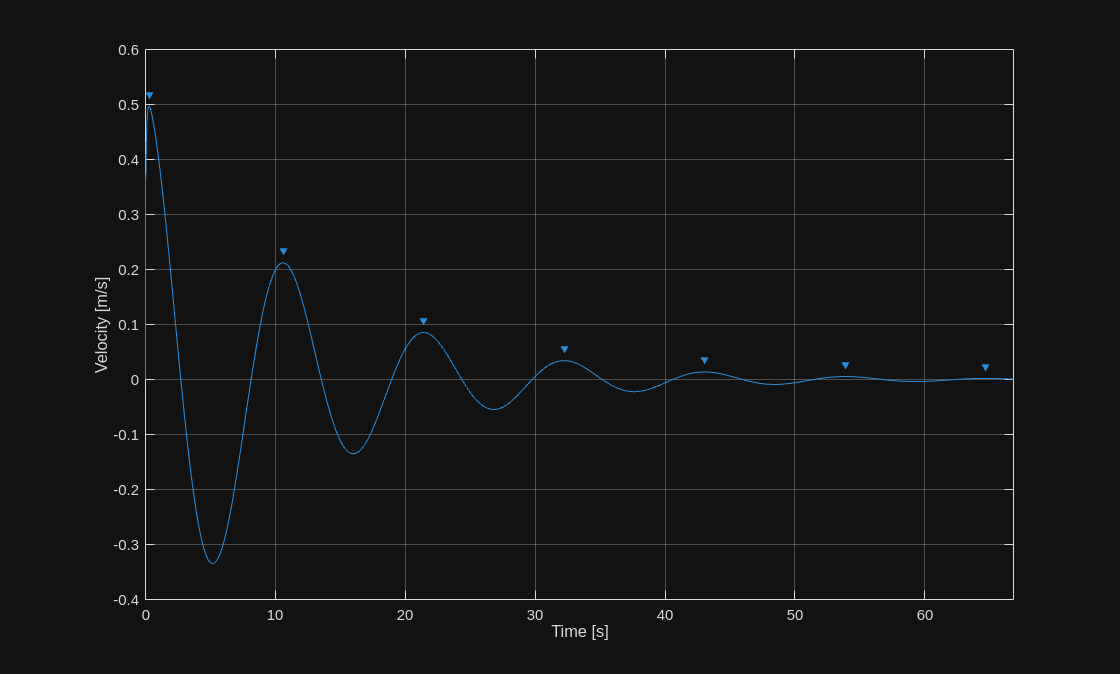

clc; clear; close all;
%load test_single_impulse_200.mat

%time = time(665:end);
%joint_velocity = joint_velocity(665:end);
%joint_
load model_joint.mat
[y,tOut] = impulse(modello_continuo);
time =tOut;
joint_velocity = y;
%plot(time, joint_position)
%xlabel("Time [s]")
%ylabel("Position [m]")
[pks,locs] = findpeaks(joint_velocity,time, MinPeakDistance=1);
findpeaks(joint_velocity,time, MinPeakDistance=1)
xlabel("Time [s]")
ylabel("Velocity [m/s]")

xi = 1/sqrt( 1+( (2*pi) / (log (locs(2)/locs(3)) ))^2)

xi = 0.1114

res = [];
for i=1:length(locs)-1
    res = [res;2*pi/(locs(i+1)-locs(i))];

end
mean(res)

ans = 0.5855

res = [];
for i=1:length(locs)-1
    res = [res;1/sqrt( 1+( (2*pi) / (log (locs(i)/locs(i+1)) ))^2)];

end
mean(res)

ans = 0.1321